********************
* SensorDataReader started on 192.168.163.90:3400
********************
Connection accepted from 192.168.163.68:39878


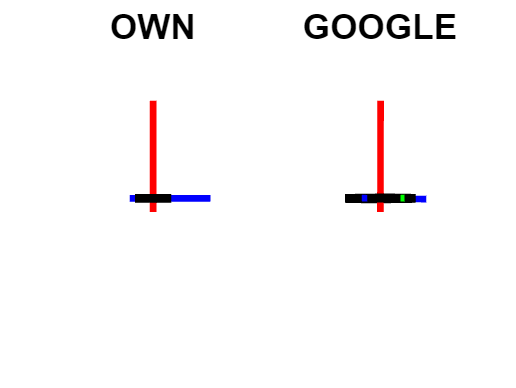

[xhat, meas] = filterTemplate();

# Task2

%filter and away from disturbance

[mu_acc, Sigma_acc] = approxGaussianTransform(meas.acc(:, ~any(isnan(meas.acc), 1)))

mu_acc =    -0.0698
    0.1296
    9.8607


Sigma_acc = 1.0e-03 *

    0.0538    0.0005   -0.0144
    0.0005    0.0416    0.0044
   -0.0144    0.0044    0.3620


[mu_gyr, Sigma_gyr] = approxGaussianTransform(meas.gyr(:, ~any(isnan(meas.gyr), 1)))

mu_gyr = 1.0e-03 *

   -0.0594
   -0.1348
    0.0545


Sigma_gyr = 1.0e-05 *

    0.0526    0.0675   -0.0118
    0.0675    0.2002   -0.0277
   -0.0118   -0.0277    0.0308


[mu_mag, Sigma_mag] = approxGaussianTransform(meas.mag(:, ~any(isnan(meas.mag), 1)))

mu_mag =    -8.9078
  -34.8681
   -6.2037


Sigma_mag =     0.0812   -0.0051    0.0049
   -0.0051    0.1222   -0.0141
    0.0049   -0.0141    0.0962


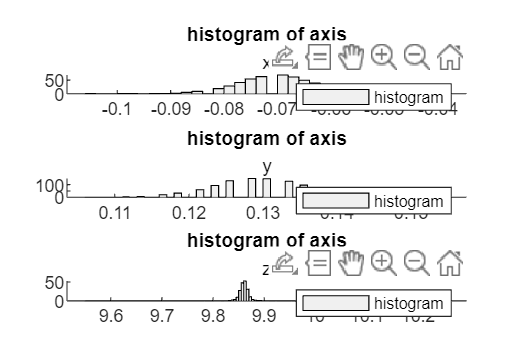

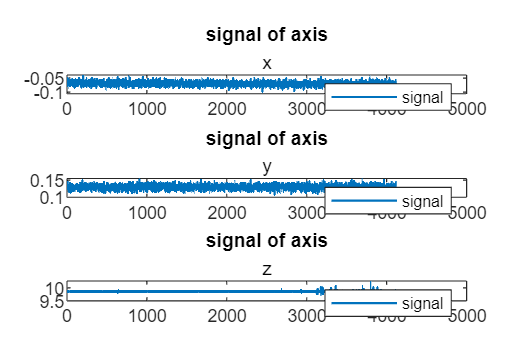

t1=meas.acc(:, ~any(isnan(meas.acc),1));
t2=meas.gyr(:, ~any(isnan(meas.gyr),1));
t3=meas.mag(:, ~any(isnan(meas.mag),1));
plothistogram(t1,mu_acc,Sigma_acc,t1);

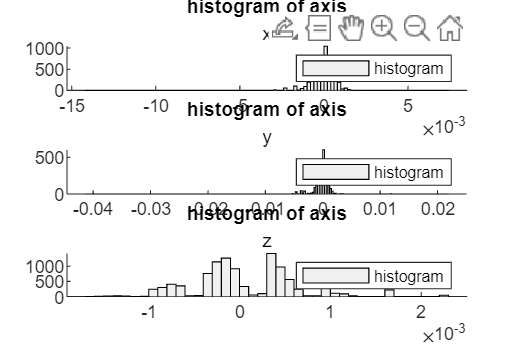

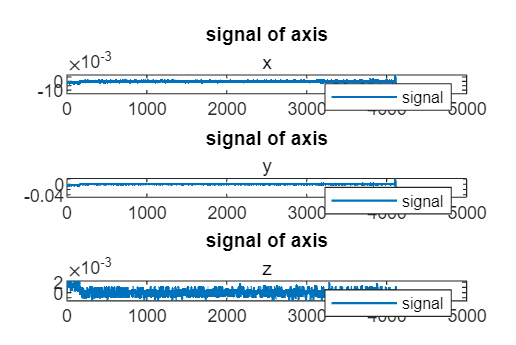

plothistogram(t2,mu_gyr,Sigma_gyr,t2);

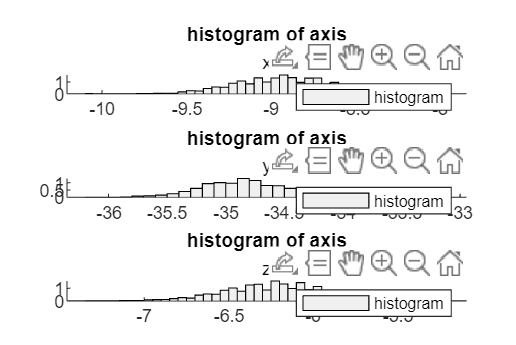

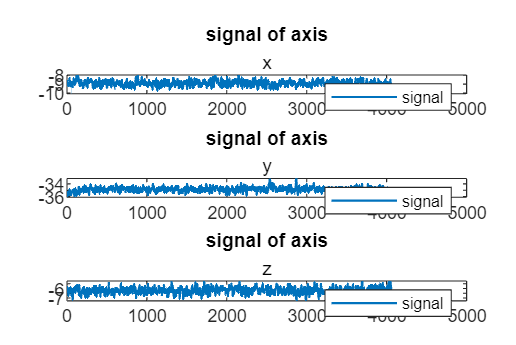

plothistogram(t3,mu_mag,Sigma_mag,t3);

# Task 3

m0=[0;35.9880;-6.2037];
norm(m0)

ans = 36.5188

# Task 4

m=[-8.90775941939827;
    -34.8681023729396;
    -6.20365672999933];
  m0=[0 sqrt(m(1)^2+m(2)^2) m(3)]'

m0 =          0
   35.9880
   -6.2037


# task 11

********************
* SensorDataReader started on 192.168.12.90:3400
********************
Connection accepted from 192.168.12.61:46962


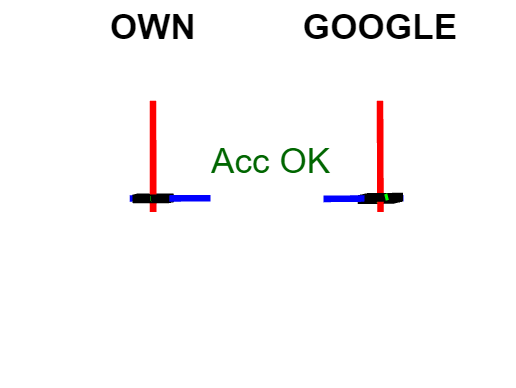

[xhat1, meas1] = filterTemplate_new();

% yaw roll pith

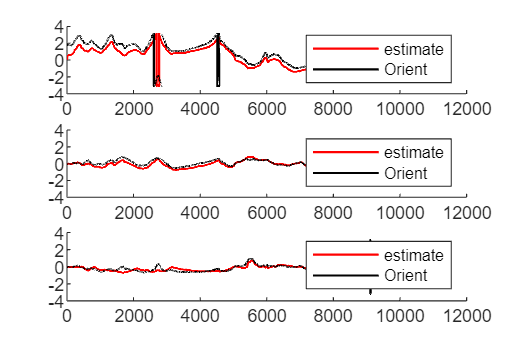

euler_est = q2euler(xhat1.x);
euler_ore = q2euler(meas1.orient);
figure('Position',[300 300 600 400]);hold on;
for i=1:3
    subplot(3,1,i);hold on
    plot(euler_est(i,:),'color','red','LineWidth',1);
    plot(euler_ore(i,:),'color','black','LineWidth',1);
    ylim([-4 4])
    legend('estimate','Orient')
end